# 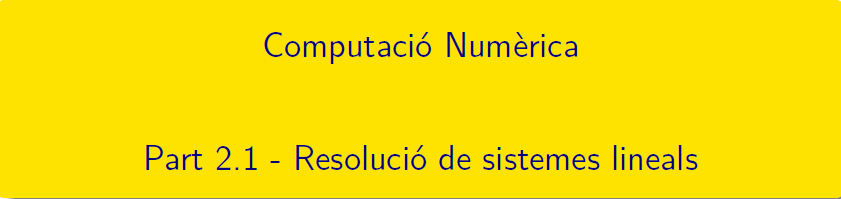

==================================================================

# TEMA 2 Àlgebra lineal numèrica

## Part 2.0 - Vectors, Matrius i Normes

### Normes de vectors

w = [1:6]'              % vector columna de matlab

w =      1
     2
     3
     4
     5
     6


v = [-5:-1:-10]'

v =     -5
    -6
    -7
    -8
    -9
   -10


v'*w                    % producte escalar = (fila x columna)

ans = -175

v*w', v'.*w', v.*w      % altres càlculs amb w i v

ans =     -5   -10   -15   -20   -25   -30
    -6   -12   -18   -24   -30   -36
    -7   -14   -21   -28   -35   -42
    -8   -16   -24   -32   -40   -48
    -9   -18   -27   -36   -45   -54
   -10   -20   -30   -40   -50   -60


ans =     -5   -12   -21   -32   -45   -60


ans =     -5
   -12
   -21
   -32
   -45
   -60


z = abs(v)              % components del vector sense signe

z =      5
     6
     7
     8
     9
    10


n1 = norm(v,1), sum(abs(v))             % norma 1    

n1 = 45

ans = 45

n2 = norm(v), sqrt(sum(v.^2))           % norma 2

n2 = 18.8414

ans = 18.8414

n3 = norm(v,'inf'), max(abs(v))         % norma del màxim

n3 = 10

ans = 10

### Normes de matrius

Moltes matrius per exemples:  ones, eye, zero, rand, randn, magic, wilkinson, hilb, invhilb, hadamard, compan, hankel, toeplitz, gallery.

A = rand(5)                 % Matrius per exemples 

A =     0.4173    0.4893    0.7803    0.1320    0.2348
    0.0497    0.3377    0.3897    0.9421    0.3532
    0.9027    0.9001    0.2417    0.9561    0.8212
    0.9448    0.3692    0.4039    0.5752    0.0154
    0.4909    0.1112    0.0965    0.0598    0.0430


sum(A),sum(A,2)

ans =     2.8053    2.2075    1.9120    2.6651    1.4676


ans =     2.0535
    2.0723
    3.8218
    2.3086
    0.8013


B = abs(A), sum(B), sum(B,2)

B =     0.4173    0.4893    0.7803    0.1320    0.2348
    0.0497    0.3377    0.3897    0.9421    0.3532
    0.9027    0.9001    0.2417    0.9561    0.8212
    0.9448    0.3692    0.4039    0.5752    0.0154
    0.4909    0.1112    0.0965    0.0598    0.0430


ans =     2.8053    2.2075    1.9120    2.6651    1.4676


ans =     2.0535
    2.0723
    3.8218
    2.3086
    0.8013


norm(A,1), sum(A)                   % norma 1

ans = 2.8053

ans =     2.8053    2.2075    1.9120    2.6651    1.4676


norm(A,2), sqrt(eig(A'*A))          % norma 2

ans = 2.4684

ans =     0.0597
    0.4859
    0.6443
    0.8312
    2.4684


norm(A,'inf')                       % norma infinit

ans = 3.8218

norm(A,'fro')                       % norma 'frobenius'

ans = 2.7274

### Tipus de matrius

Biblioteca de [matrius en Matlab](https://es.mathworks.com/help/matlab/constants-and-test-matrices.html?lang=en), i més matrius en Matlab [gallery](https://es.mathworks.com/help/matlab/ref/gallery.html)

format rat
H = hilb(4), A = H-2*ones(size(H))

H =        1              1/2            1/3            1/4     
       1/2            1/3            1/4            1/5     
       1/3            1/4            1/5            1/6     
       1/4            1/5            1/6            1/7     


A =       -1             -3/2           -5/3           -7/4     
      -3/2           -5/3           -7/4           -9/5     
      -5/3           -7/4           -9/5          -11/6     
      -7/4           -9/5          -11/6          -13/7     


% A = ones(5),zeros(5),eye(5) 
triu(H), triu(H, 1)

ans =        1              1/2            1/3            1/4     
       0              1/3            1/4            1/5     
       0              0              1/5            1/6     
       0              0              0              1/7     


ans =        0              1/2            1/3            1/4     
       0              0              1/4            1/5     
       0              0              0              1/6     
       0              0              0              0       


tril(H), tril(H,-1)

ans =        1              0              0              0       
       1/2            1/3            0              0       
       1/3            1/4            1/5            0       
       1/4            1/5            1/6            1/7     


ans =        0              0              0              0       
       1/2            0              0              0       
       1/3            1/4            0              0       
       1/4            1/5            1/6            0       


diag(diag(H))

ans =        1              0              0              0       
       0              1/3            0              0       
       0              0              1/5            0       
       0              0              0              1/7     


format
C = rand(5)

C =     0.1622    0.6020    0.4505    0.8258    0.1067
    0.7943    0.2630    0.0838    0.5383    0.9619
    0.3112    0.6541    0.2290    0.9961    0.0046
    0.5285    0.6892    0.9133    0.0782    0.7749
    0.1656    0.7482    0.1524    0.4427    0.8173


B = (C'+C)/2       % Simètrica

B =     0.1622    0.6981    0.3809    0.6772    0.1362
    0.6981    0.2630    0.3690    0.6138    0.8550
    0.3809    0.3690    0.2290    0.9547    0.0785
    0.6772    0.6138    0.9547    0.0782    0.6088
    0.1362    0.8550    0.0785    0.6088    0.8173


Ba = (C-C')/2      % Antisimètrica

Ba =          0   -0.0962    0.0697    0.1486   -0.0295
    0.0962         0   -0.2851   -0.0754    0.1069
   -0.0697    0.2851         0    0.0414   -0.0739
   -0.1486    0.0754   -0.0414         0    0.1661
    0.0295   -0.1069    0.0739   -0.1661         0


B + Ba == C

ans = 5×5 logical array
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   0   1   1   1   1
   1   1   1   1   1


### Exercici 3: Tranformacions ortogonals

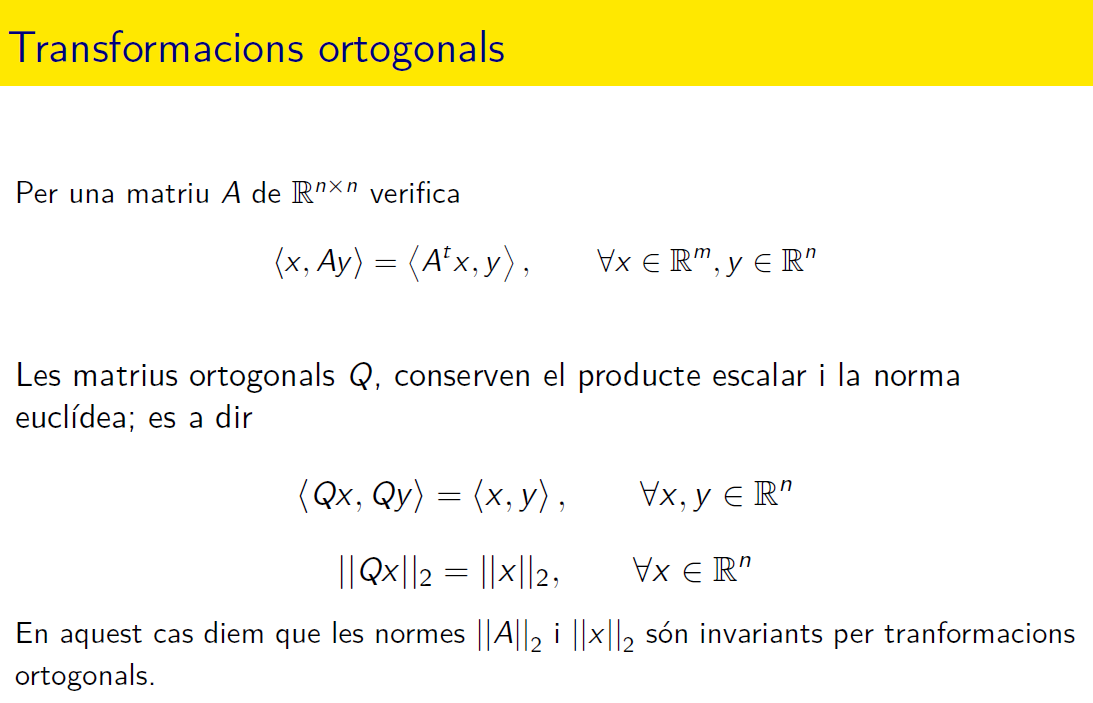

a) Verifica la propietat <x,Ay> = <A^tx,y> per a qualsevol matriu A quadrada.

format shortG
% x'*(Ay)  =  (A'*x)'*y
A = gallery('lehmer',5)     % Una matriu de la biblioteca

A =             1          0.5      0.33333         0.25          0.2
          0.5            1      0.66667          0.5          0.4
      0.33333      0.66667            1         0.75          0.6
         0.25          0.5         0.75            1          0.8
          0.2          0.4          0.6          0.8            1


x = ones(5,1); y = diag(hilb(5));   [x,y]  % dos vectors columna

ans =             1            1
            1      0.33333
            1          0.2
            1      0.14286
            1      0.11111


[x'*(A*y), (A'*x)'*y]

ans =        4.7803       4.7803


b) Verifica la propietat <Qx,Qy> = <x,y> per a qualsevol matriu Q ortogonal.

Q = gallery('orthog',5)    % Una matriu ortogonal de la biblioteca

Q =       0.28868          0.5      0.57735          0.5      0.28868
          0.5          0.5            0         -0.5         -0.5
      0.57735            0     -0.57735            0      0.57735
          0.5         -0.5            0          0.5         -0.5
      0.28868         -0.5      0.57735         -0.5      0.28868


x = ones(5,1); y = diag(hilb(5)); [x,y]      % dos vectors columna

ans =             1            1
            1      0.33333
            1          0.2
            1      0.14286
            1      0.11111


[(Q*x)'*(Q*y), x'*y]

ans =        1.7873       1.7873


### Radi espectral 

rho = abs(eigs(Q,1))

rho =             1


### Nombre de condició d'una matriu

cond(A), det(A), rcond(A)

ans =        19.655


ans =      0.065625


ans =       0.05597


## Part 2.1 - Resolució de sistemas d'equacions lineals

### Resolució de sistemes lineales amb Matlab

A = [6 2 -1 -1; 2 4 -1 0; -1 1 4 -1; -1 0 -1 3]

A =      6     2    -1    -1
     2     4    -1     0
    -1     1     4    -1
    -1     0    -1     3


b = [0; 7; -1; 2]

b =      0
     7
    -1
     2


det(A)          % determinant

ans =           201


rank(A)         % rang

ans =      4


rank([A,b])     % rang matriu ampliada

ans =      4


sol = A\b

sol =      -0.76617
       1.9104
     -0.89055
      0.11443


 vector_residu = norm(A*sol-b)

vector_residu =    1.1116e-15


### Vector residu

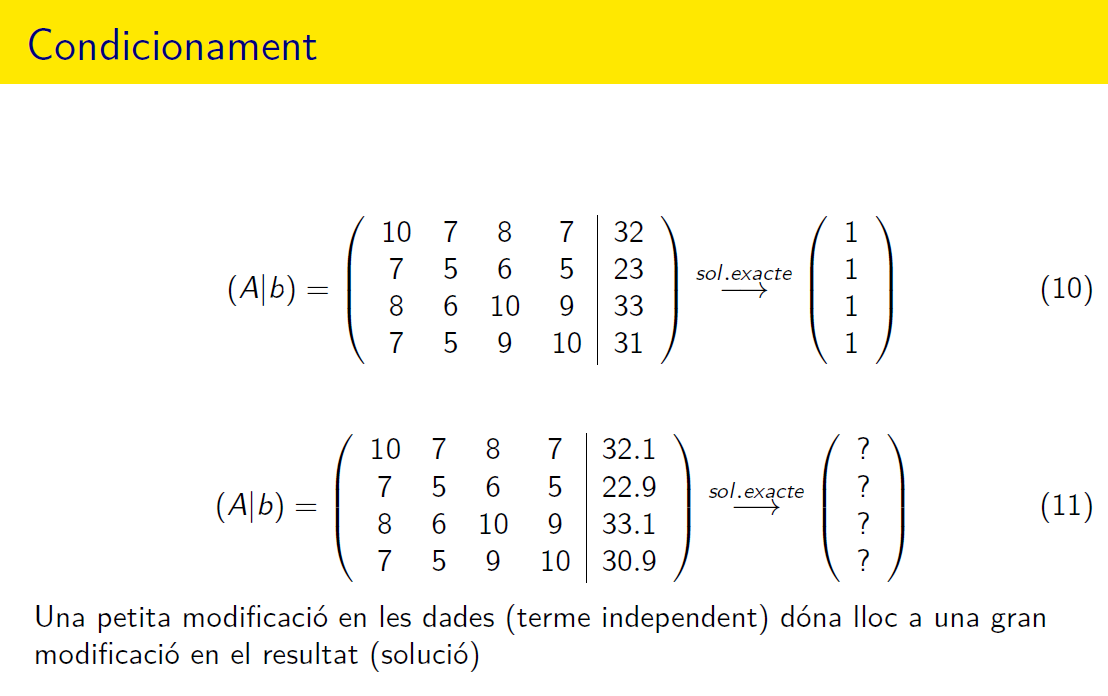

A = [10 7 8 7; 7 5 6 5; 8 6 10 9; 7 5 9 10];
b1 = [32; 23; 33; 31];
b2 = [32.1; 22.9; 33.1; 30.9];
B = [b1,b2], x = A\B

B =            32         32.1
           23         22.9
           33         33.1
           31         30.9


x =             1          9.2
            1        -12.6
            1          4.5
            1         -1.1


fprintf('paràmetres de condicionament\n'),K=cond(A,1), RK=rcond(A)  % mal condicionada

paràmetres de condicionament


K =          4488


RK =    0.00022282


fprintf('vector residu\n'),rx = A*x-B

vector residu


rx =             0  -1.4211e-14
            0  -7.1054e-15
            0  -7.1054e-15
            0  -1.0658e-14
